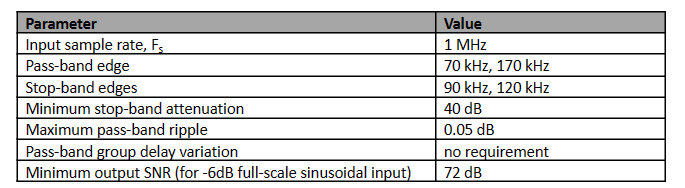

fs = 1e6

fs = 1000000

fp1 = 70e3;
fp2 = 170e3;
fs1 = 90e3;
fs2 = 120e3;
Atten = 40

Atten = 40

PBRipple = 0.05

PBRipple = 0.0500

SNR = 72

SNR = 72


wp1 = 2*fp1/fs

wp1 = 0.1400

wp1 = wp1 * pi;

wp2 = 2*fp2/fs

wp2 = 0.3400

wp2 = wp2 * pi;

ws1 = 2*fs1/fs

ws1 = 0.1800

ws1 = ws1 * pi;

ws2 = 2*fs2/fs

ws2 = 0.2400

ws2 = ws2 * pi;


Low Pass Filter


wc = 0.1 *pi; %arbitrary
lambda=(cos((wp2+wp1)/2))/(cos((wp2-wp1)/2))

lambda = 0.7665


% % BandPass
% wp1 = 0.46*pi
% wp2 = 0.66*pi
% ws1 = 0.31*pi
% ws2 = 0.76*pi
% p = cot((wp2-wp1)/2)*tan(wc/2)
% w_hat = ws2
% w = abs(2*atan(-1*p*(lambda - cos(w_hat))/sin(w_hat)))/pi

%% BandStop
p = tan((wp2-wp1)/2)*tan(wc/2)

p = 0.0515

ws1_hat = abs(2*atan(p*sin(ws1)/(cos(ws1)-lambda)))/pi

ws1_hat = 0.2167

ws1_hat = ws1_hat *pi;
ws2_hat = abs(2*atan(p*sin(ws2)/(cos(ws2)-lambda)))/pi

ws2_hat = 0.4800

ws2_hat = ws2_hat *pi;

%% chose more stringent stopband freq
if ws1<ws2
    ws_hat = ws1_hat;
else
    ws_hat = ws2_hat;
end

wp_hat = wc

wp_hat = 0.3142


%%prewarp
omega_p = tan(wp_hat/2)

omega_p = 0.1584

omega_s = tan(ws_hat/2)

omega_s = 0.3542

syms x
eqn = 20*log10(sqrt(1+x^2)) == PBRipple;
epsilon = double(solve(eqn));
epsilon = epsilon(1)

epsilon = 0.1076

eqn = 20*log10(x) == Atten;
A = double(solve(eqn))

A = 100


k = omega_p/omega_s

k = 0.4471

k1 = epsilon/(sqrt(A^2-1))

k1 = 0.0011

k1 = k1(1)

k1 = 0.0011

N = acosh(1/k1)/acosh(1/k); %minimum order number
N = ceil(N)

N = 6

%doesnt consider attenuation, only epsilon (passband ripple)
%will use [z,p,k] = cheb1ap(10,6);
alpha = 1/epsilon + sqrt(1+1/epsilon^2)

alpha = 18.6396

a = (alpha^(1/N) - alpha^(-1/N))/2

a = 0.5071

b = (alpha^(1/N) + alpha^(-1/N))/2

b = 1.1212


%use iirlp2bs to create digital transform, not formulas
%needs analog filter a and b - use [z,p,k] = cheb1ap(10,6);
% refer to bilinear ellip example for poles and zeroes

fc = 100e3 %arbitrary

fc = 100000

fs = 1e6

fs = 1000000


wt = [wp1/pi wp2/pi]

wt =     0.1400    0.3400


wo = fc/(fs/2) %what should this be?

wo = 0.2000

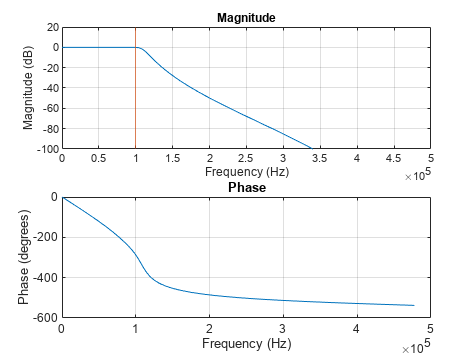


[b,a] = cheby1(order,PBRipple,wo);
freqz(b,a,[],fs)
xline(fc,Color=[0.8500 0.3250 0.0980])
subplot(2,1,1)
ylim([-100 20])


[num,den] = iirlp2bs(b,a,wo,wt);
hfvt = fvtool(b,a,num,den);
legend(hfvt,"Prototype Filter (TF Form)",...
    "Transformed Bandstop Filter")